# Generalized Conway's Game of Life

## 設定

- T                ：シミュレーション回数

- n                ：エリアのサイズ

- d                ：近傍の半径

- alive_min   ：近傍の生存セル数の最小値（生存）

- alive_max  ：近傍の生存セル数の最大値（生存）

- birth_min   ：近傍の生存セル数の最小値（誕生）

- birth_max  ：近傍の生存セル数の最小値（誕生）

- movie        ：動画の表示の有無

- resize        ：保存画像のリサイズの有無


%Parameters
T = 10000;
n = 237;
d = 1;
alive_min = (2*d+1)^2 *0.221;
alive_max = (2*d+1)^2 *0.6591;
birth_min = (2*d+1)^2 *0.31; 
birth_max = (2*d+1)^2 *0.5496;
exit_conditions = 0;
movie = true;
resize = true;

## 実行

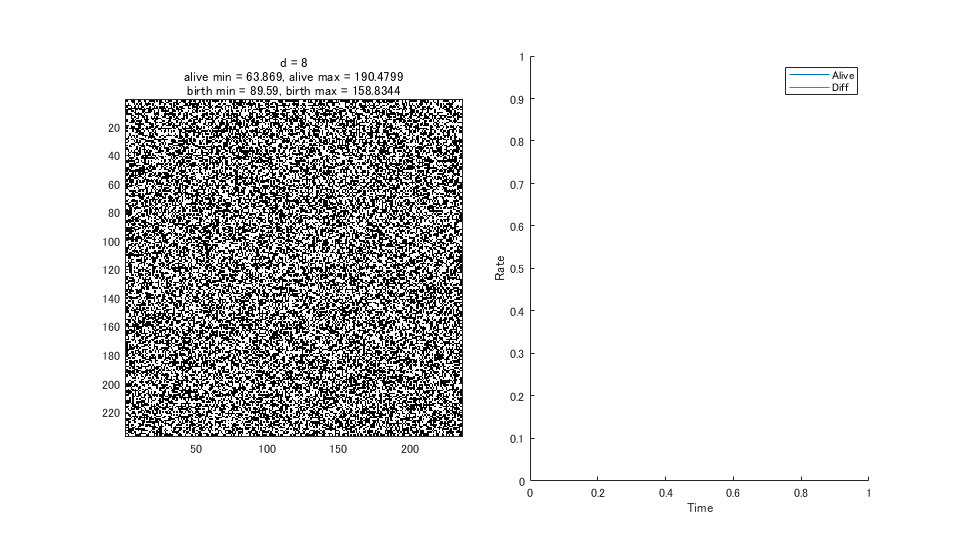

M = rand(n) > 0.5;

alive = zeros(T+1,1);
alive(1) = sum(M,"all");
diff_alive = zeros(T+1,1);
diff_alive(1) = 0;

tic
figure("Position",[0,0,1920/2,1080/2]);
for t = 1:T
    %Visualize
    if movie == true
        cla
        tiledlayout(1,2,"TileSpacing","compact")
        nexttile;
        image(M*255);    
        colormap gray 
        pbaspect([1 1 1]);
        title(["d = "+num2str(d) ...
               "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
               "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])
        nexttile;
        hold on
        plot(alive(1:t)./n^2);
        plot(diff_alive(1:t)./n^2);
        legend(["Alive","Diff"]);
        xlim([-inf inf]);
        ylim([0 1]);
        xlabel("Time");
        ylabel("Rate")
        hold off
        drawnow
    end
    
    A = ones(2*d+1);
    A(d+1,d+1) = 0;

    temp = conv2(padarray(M,[d,d],0,'circular'),A,"same");
    S = temp(d+1:n+d,d+1:n+d);
    M_next = M.*(alive_min<=S).*(S<=alive_max)+...
        (1-M).*(birth_min<=S).*(S<=birth_max);
    
    alive(t+1) = sum(M_next,"all");
    diff_alive(t+1) = sum(abs(M-M_next),"all");
    
    if sum(abs(M-M_next)./n^2,"all") < 0.05
        break
    end
    
    M = M_next;
end

clf
image(M*255);    colormap gray 
pbaspect([1 1 1]);
title(["d = "+num2str(d), ...
       "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
       "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])
imwrite(imresize(M*255,[1024,1024],"nearest"),"result.png");